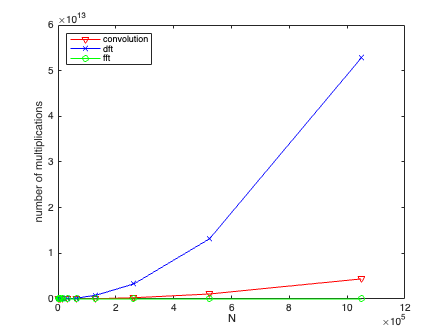

% HW 8
% Prob 3.d
n = 2:20;
N = 2 .^ n;
conv_nm = 4 * N .^ 2;
dft_nm = 48 * N .^ 2 + 8*N;
fft_nm = 12 * N .* log2(2*N) + 8 * N;

plot(N,conv_nm,'rv-', N, dft_nm, 'bx-', N, fft_nm, 'go-')
legend('convolution','dft','fft', 'Location','northwest')
xlabel('N');
ylabel('number of multiplications');

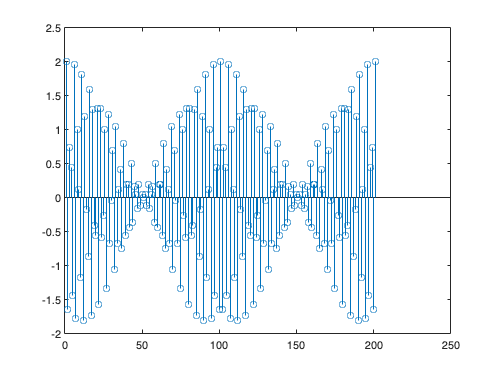

% HW 8
% Prob 4
load hw8signal.mat;
stem(x);

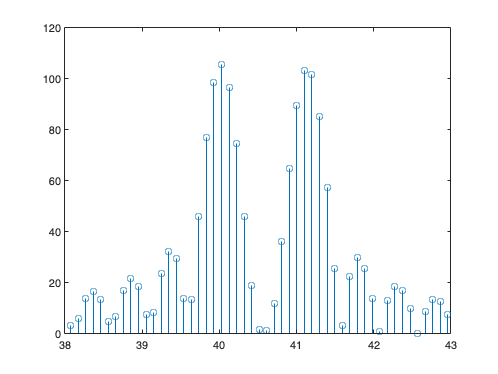

% it seems there might be 3 frequency components in the signal
% one of which seems very low in amplitude
Fs = 100;
N = length(x);
y = fftshift(fft(x,1024));
f = -Fs/2:Fs/(length(y)-1):Fs/2;
figure;
stem(f, abs(y));
% we manually iterate through the graph to see closer to the peaks
% it seems there are 2 peaks, one around 40, and one around 41
% the 2 peaks do not look symmetric, and given how it seemed there 
% were 3 components we should try a different window
axis([38 43 0 120])

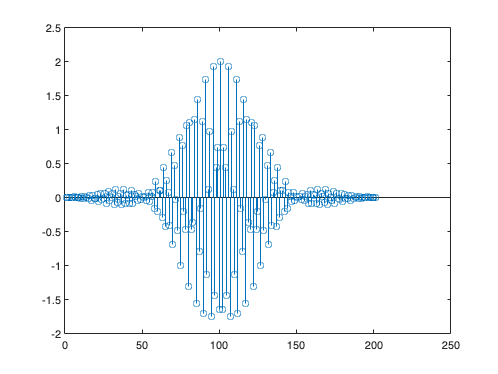


figure;
clear kh;
wh = kaiser(length(x),9)';
xh = x .* wh;
stem(xh);

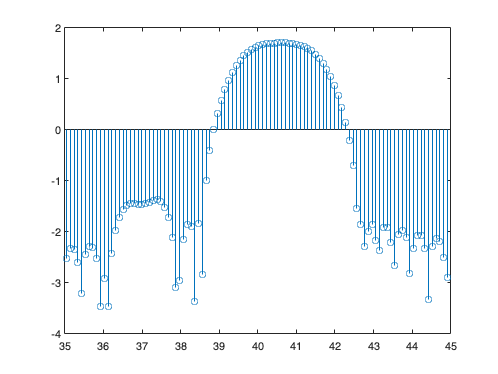

figure;
yh = fftshift(fft(xh, 1024));
% we manually iterate through the graph to see closer
% as we cannot see anything in the linear graph we plot a 
% log graph and manipulate axis to zoom in around relevant
% frequencies. From this grph we can see there is a component
% around 37 Hz
stem(f,log10(abs(yh)))
xticks(35:45);
axis([35 45 -4 2])


% The frequency components of the signal are: 37, 40, 41 Hz

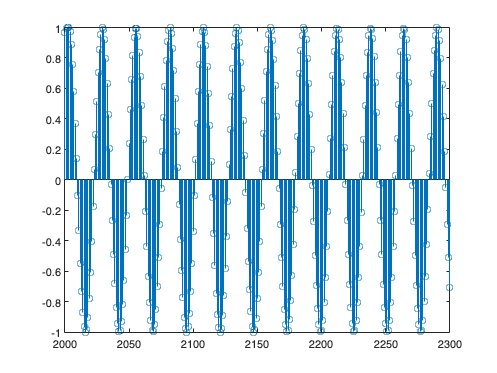

% HW 8, Problem 5
Fs = 1000;
Ts = 1/Fs;
t1 = 0:Ts:1;
t2 = 2:Ts:3;
t4 = 4:Ts:5;
s1 = cos(2*pi*10*t1);
s2 = cos(2*pi*20*t2);
s4 = chirp(t4,30,5,40);


s = [s1 s2 s4];
figure;
stem(s)
axis([2000 2300 -1 1])

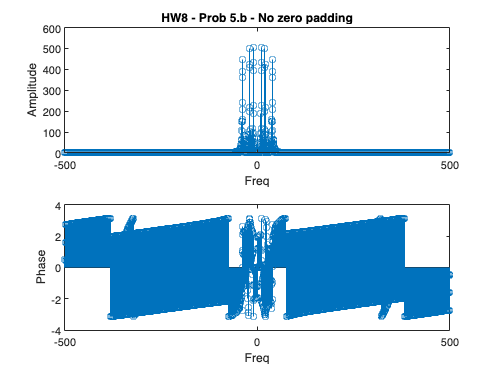

figure;
y = fftshift(fft(s));
f = -Fs/2:Fs/(length(y)-1):Fs/2;
figure;
subplot(2,1,1);
stem(f, abs(y));
title('HW8 - Prob 5.b - No zero padding')
xlabel('Freq');
ylabel('Amplitude')
subplot(2,1,2);
stem(f,angle(y));
xlabel('Freq');
ylabel('Phase')

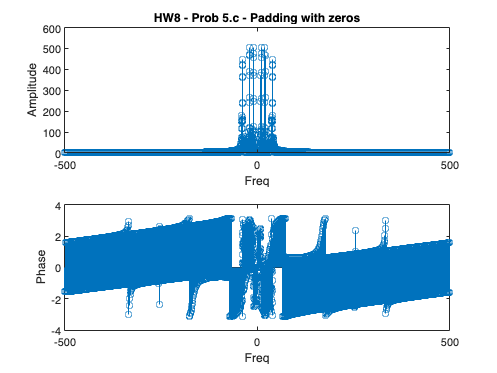


figure;
t15 = 0:Ts:5;
s0 = zeros(1,length(t15));
s0(t15>=0 & t15<=1) = s1;
s0(t15>=2 & t15<=3) = s2;
s0(t15>=4 & t15<=5) = s4;
y0 = fftshift(fft(s0));
f0 = -Fs/2:Fs/(length(y0)-1):Fs/2;
subplot(2,1,1);
stem(f0, abs(y0));
title('HW8 - Prob 5.c - Padding with zeros')
xlabel('Freq');
ylabel('Amplitude');
subplot(2,1,2);
stem(f0,angle(y0));
xlabel('Freq');
ylabel('Phase');

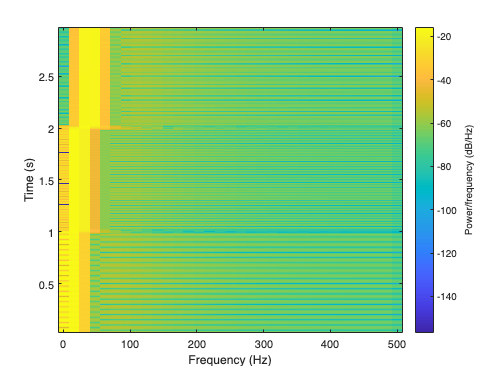

% There is no difference, as the time information is lost in
% FFT, but zooming in, padding with 0's will provide greater
% detail
figure;
spectrogram(s,64,60,64,Fs)

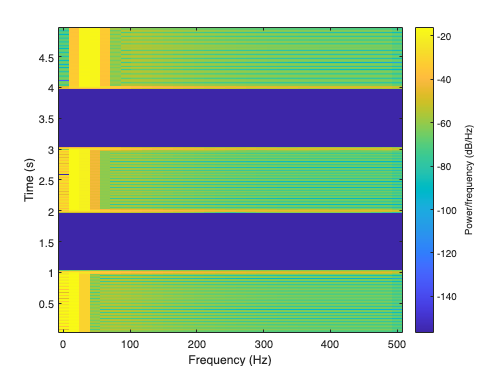

figure;
spectrogram(s0,64,60,64,Fs)

[A, f, t] = dynamic_spectra(s0,256,10,1000);

Ls = 5001

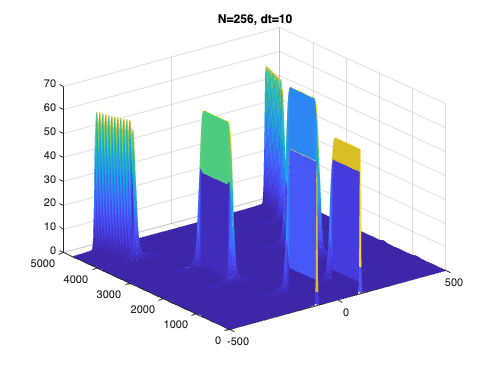

mesh(f,t,abs(A))
title('N=256, dt=10')


[A, f, t] = dynamic_spectra(s0,64,10,1000);

Ls = 5001

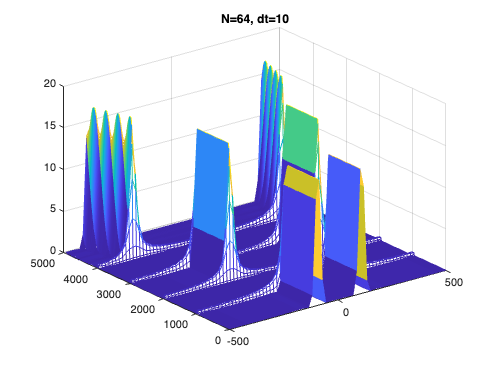

figure
mesh(f,t,abs(A))
title('N=64, dt=10')


[A, f, t] = dynamic_spectra(s0,256,500,1000);

Ls = 5001

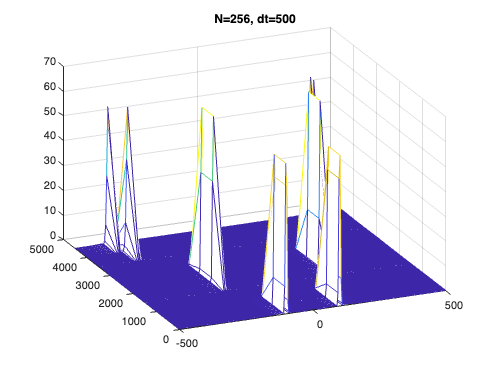

figure
mesh(f,t,abs(A))
title('N=256, dt=500')


[A, f, t] = dynamic_spectra(s0,64,500,1000);

Ls = 5001

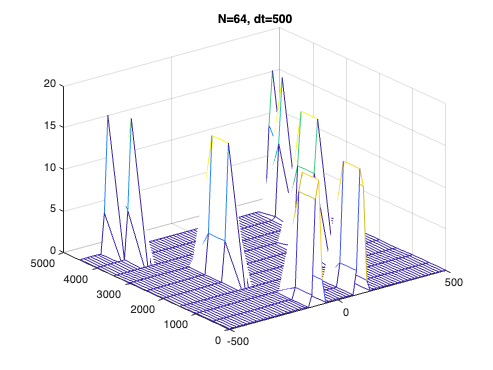

figure
mesh(f,t,abs(A))
title('N=64, dt=500')

% With increase in N we see greater detail in the frequency
% plots. As dt increases, we see discontinuity in the chirp
% signal, as it does not have single frequency, thus we see
% the effects of temporal resolution affecting outcome 

function [A, f, t] = dynamic_spectra(s, N, dt, fs)
Ls = length(s)

K = floor((Ls-N)/dt); % number of blocks is K+1
s = [s zeros(1,N-1)];
A = zeros(K+1,N);
f = -fs/2:fs/(N-1):fs/2;
t = [];
h = hamming(N)';
for n=0:K
    t = [t n*dt + 1];
    xn = s(1,n*dt+1:n*dt+N) .* h;
    A(n+1,:) = fftshift(fft(xn, N));
end


end
